# **AR vs. ARMA Model**

**Create Autoregressive Data**

% Generate synthetic data for AR model
n = 100; % number of observations
ar_params = [0.75, -0.5]; % AR parameters
noise_std = 0.5; % noise standard deviation

rng(1); % for reproducibility
ar_data = arima('Constant',0,'AR',ar_params,'Variance',noise_std^2);
data_ar = simulate(ar_data, n);

% Fit AR model to the data
model_ar = arima('ARLags',1:2,'Constant',0);
fit_ar = estimate(model_ar, data_ar);

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           0             0            NaN             NaN
    AR{1}        0.59666       0.10303         5.7909      6.9997e-09
    AR{2}       -0.39221      0.081141        -4.8337      1.3401e-06
    Variance     0.23563      0.039432         5.9757      2.2916e-09



data_AR_Infer = infer(fit_ar,data_ar);

% Display results
disp('AR Model:')

AR Model:


disp(fit_ar)

  arima with properties:

     Description: "ARIMA(2,0,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 0
        Constant: 0
              AR: {0.596659 -0.392211} at lags [1 2]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.235631


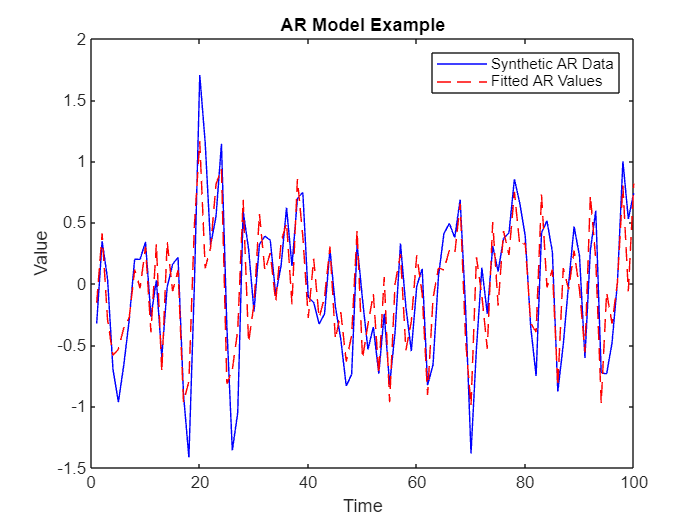


% Plot the synthetic data and the fitted values
figure;
plot(data_ar, 'b', 'DisplayName', 'Synthetic AR Data');
hold on;
plot(data_AR_Infer, 'r--', 'DisplayName', 'Fitted AR Values');
legend;
title('AR Model Example');
xlabel('Time');
ylabel('Value');